% drone.m;
clear
drone = Drone(zeros(100,100), 5, 5, 2)

drone =   Drone with properties:

            TrueMap: [100×100 double]
           DroneMap: [100×100 double]
                  X: 5
                  Y: 5
             DeltaX: 0
             DeltaY: 0
           MaxSpeed: 2
       Acceleration: 0.4000
          KDistance: 0.2500
        DDerivative: 1
    SensingDistance: 3


for i = 1:10
drone = drone.navigateToPoint(8, 8);
end
drone

drone =   Drone with properties:

            TrueMap: [100×100 double]
           DroneMap: [100×100 double]
                  X: 7.7846
                  Y: 7.7846
             DeltaX: 0.0718
             DeltaY: 0.0718
           MaxSpeed: 2
       Acceleration: 0.4000
          KDistance: 0.2500
        DDerivative: 1
    SensingDistance: 3


map = randi([0 1], 100, 100, "double");
drone = Drone(map, 5, 5, 10);

Warning!!! Max speed of drone is too great for the sensing capability currently set. The drone may fly faster than its sensing area.


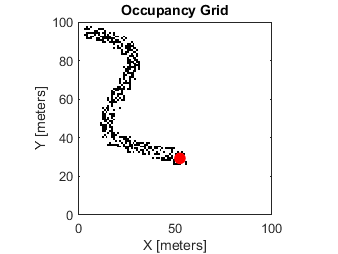

targets = [20, 10; 15, 50; 50, 70];
for i = 1:size(targets, 1)
    targetX = targets(i,1);
    targetY = targets(i,2);
    count = 0;
    while ~drone.isNear(targetX,targetY)
        drone = drone.navigateWithSpeed(targetX,targetY, 0.6);
        drone.plot();
        pause(0.1);
        if count > 50
            break;
        end
        count = count +1;
    end
end